# Measurement data of OL490 simulating CIE illuminants on 6/17/2022, 62/3133 (HIMS2)

For LightSim paper, 12/1/2022

Q: How to evaluate like Tommy Wei's and Ling Ma's papers

A: SAM

## Reference data

CIE D: my class based on formula

CIE F: my class based on Excel data

CIE A: from "C:\Users\wayne\Documents\GitHub\lightmatching\datain" (9/24/2015)

CIE E: my creation

## Input data (A matrix) are pre-computed 1024 vec for OL490

ls input/A_*

A_a.mat    A_f1.mat   A_f2.mat   A_f6.mat   
A_d50.mat  A_f10.mat  A_f3.mat   A_f7.mat   
A_d65.mat  A_f11.mat  A_f4.mat   A_f8.mat   
A_e.mat    A_f12.mat  A_f5.mat   A_f9.mat   



## Reference data (spectra): cannot recall...

ls ref/spec*

spec_ciea.mat  spec_ciee.mat  



## Conduct the measurement

%% conduct the measurement
% main_cie2A

## Output data from OL490

ls output/s_*

s_a.mat    s_f1.mat   s_f2.mat   s_f6.mat   
s_d50.mat  s_f10.mat  s_f3.mat   s_f7.mat   
s_d65.mat  s_f11.mat  s_f4.mat   s_f8.mat   
s_e.mat    s_f12.mat  s_f5.mat   s_f9.mat   



## Show CIE D findings

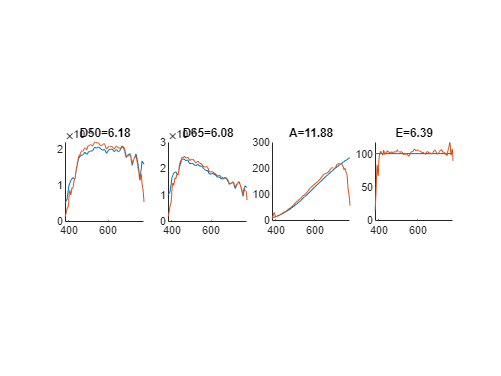

clf

%
% D50
%
fn = 'output/s_d50';
load(fn)
s_di_mea = s.amplitude;
s_di_mea_auc = sum(s_di_mea);

s_di_ref = CIE_D.getSpectrum(5000).amplitude;
s_di_ref_auc = sum(s_di_ref);

sam_val = rad2deg(sam(s_di_ref,s_di_mea));

subplot(1,4,1)
hold on
plot(380:780,s_di_ref)
plot(380:780,s_di_mea * s_di_ref_auc / s_di_mea_auc)

sam_str = sprintf('D50=%.2f',sam_val);
title(sam_str)

axis square

%
% D65
%
fn = 'output/s_d65';
load(fn)
s_di_mea = s.amplitude;
s_di_mea_auc = sum(s_di_mea);

s_di_ref = CIE_D.getSpectrum(6500).amplitude;
s_di_ref_auc = sum(s_di_ref);

sam_val = rad2deg(sam(s_di_ref,s_di_mea));

%%
subplot(1,4,2)
hold on
plot(380:780,s_di_ref)
plot(380:780,s_di_mea * s_di_ref_auc / s_di_mea_auc)

sam_str = sprintf('D65=%.2f',sam_val);
title(sam_str)

axis square

%
% A
%
fn = 'output/s_a';
load(fn)
s_di_mea = s.amplitude;
s_di_mea_auc = sum(s_di_mea);

load('ref/spec_ciea.mat')
s_di_ref = spec(:,2);
s_di_ref_auc = sum(s_di_ref);

sam_val = rad2deg(sam(s_di_ref,s_di_mea));

subplot(1,4,3)
hold on
plot(380:780,s_di_ref)
plot(380:780,s_di_mea * s_di_ref_auc / s_di_mea_auc)

sam_str = sprintf('A=%.2f',sam_val);
title(sam_str)

axis square

%
% E
%
fn = 'output/s_e';
load(fn)
s_di_mea = s.amplitude;
s_di_mea_auc = sum(s_di_mea);

load('ref/spec_ciee.mat')
s_di_ref = spec(:,2);
s_di_ref_auc = sum(s_di_ref);

sam_val = rad2deg(sam(s_di_ref,s_di_mea));

subplot(1,4,4)
hold on
plot(380:780,s_di_ref)
plot(380:780,s_di_mea * s_di_ref_auc / s_di_mea_auc)

sam_str = sprintf('E=%.2f',sam_val);
title(sam_str)

axis square

## Show CIE F findings

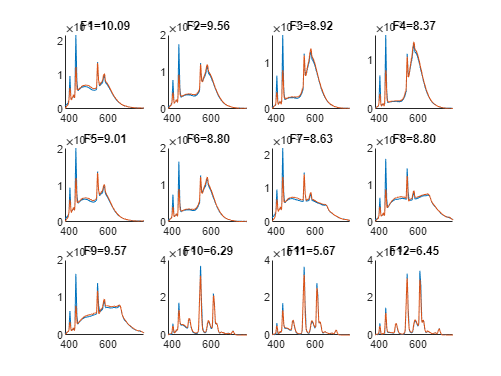

clf
for i = 1:12

    s_fi_ref = CIE_F.getSpectrum(i).amplitude;
    s_fi_ref_auc = sum(s_fi_ref);

    fn = sprintf('output/s_f%d',i);
    load(fn);
    s_fi_mea = s.amplitude;
    s_fi_mea_auc = sum(s_fi_mea);

    % [s_fi_ref_auc s_fi_mea_auc] 
    sam_val = rad2deg(sam(s_fi_ref,s_fi_mea));

    subplot(3,4,i)
    hold on
    plot(380:780,s_fi_ref)
    plot(380:780,s_fi_mea * s_fi_ref_auc / s_fi_mea_auc)
    
    sam_str = sprintf('F%d=%.2f',i,sam_val);
    title(sam_str)

end

## Combine D and F

12/4/2022

mea16 = zeros(16,401);
ref16 = zeros(16,401);
name16 = {};

%
% D65
%
i = 1;
fn = 'output/s_d65';
load(fn)
mea16(i,:) = s.amplitude;
ref16(i,:) = CIE_D.getSpectrum(6500).amplitude;
name16{i} = 'D65';

%
% D50
%
i = 2;
fn = 'output/s_d50';
load(fn)
mea16(i,:) = s.amplitude;
ref16(i,:) = CIE_D.getSpectrum(5000).amplitude;
name16{i} = 'D50';

%
% A
%
i = 3;
fn = 'output/s_a';
load(fn)
mea16(i,:) = s.amplitude;

load('ref/spec_ciea.mat')
ref16(i,:) = spec(:,2)';
name16{i} = 'A';

%
% E
%
i = 4;
fn = 'output/s_e';
load(fn)
mea16(i,:) = s.amplitude;

load('ref/spec_ciee.mat')
ref16(i,:) = spec(:,2)';
name16{i} = 'E';

%
% F
%
for i = 1:12
    ref16(i+4,:) = CIE_F.getSpectrum(i).amplitude;

    fn = sprintf('output/s_f%d',i);
    load(fn);
    mea16(i+4,:) = s.amplitude;
    name16{i+4} = sprintf('F%d',i);
end

## Normalize data

ref16 = ref16 ./ sum(ref16,2);
mea16 = mea16 ./ sum(mea16,2);

## Generate plot

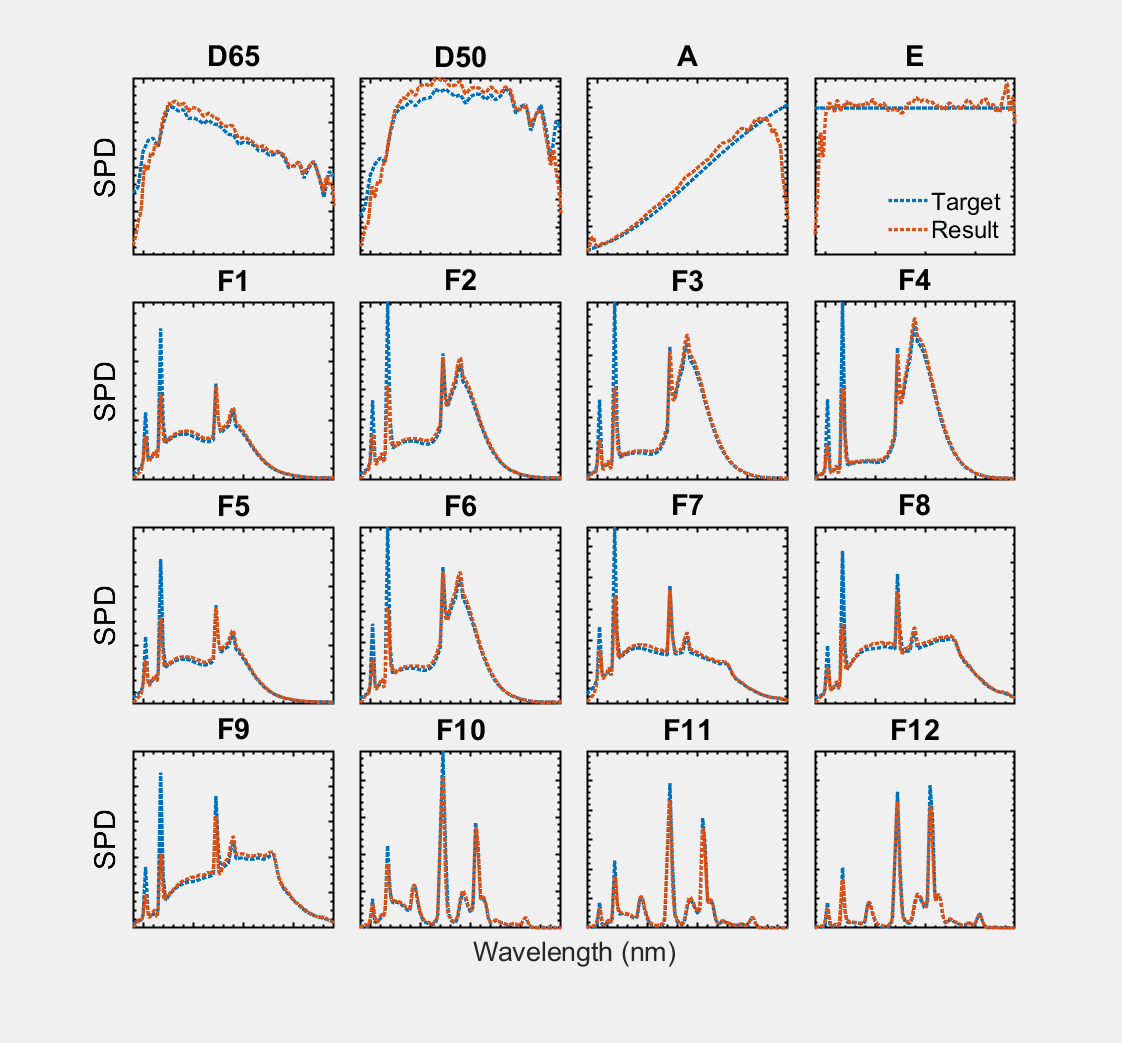

clf
td = tiledlayout(4,4,'TileSpacing','compact');
hg = gcf;
set(hg,'Visible','on');
for idx = 1:16
    haxis = nexttile(idx);
    hold on
    plot(380:780,ref16(idx,:),':')
    plot(380:780,mea16(idx,:),':')
    title(name16{idx})
    xticklabels({});
    yticklabels({});
    PlotBeautify(haxis)
    legend off

        if idx < 9
            xticklabels({});
        end
        
        yticklabels({});

        if mod(idx,4)==1
            ylabel('SPD');
        end

        switch idx
            case 4
                lgd = legend('Target','Result','Location','southeast');
                lgd.Box = 'off';
        end    
end
td.XLabel.String = 'Wavelength (nm)';
td.XLabel.FontSize = 20;

hg.Position = [579 57 1122 1043];
saveas(hg,'spectrum16.png')

## PSNR, SAM, and CIE u'v' evaluation

ISO 23603 criterion is du'v' < 0.015

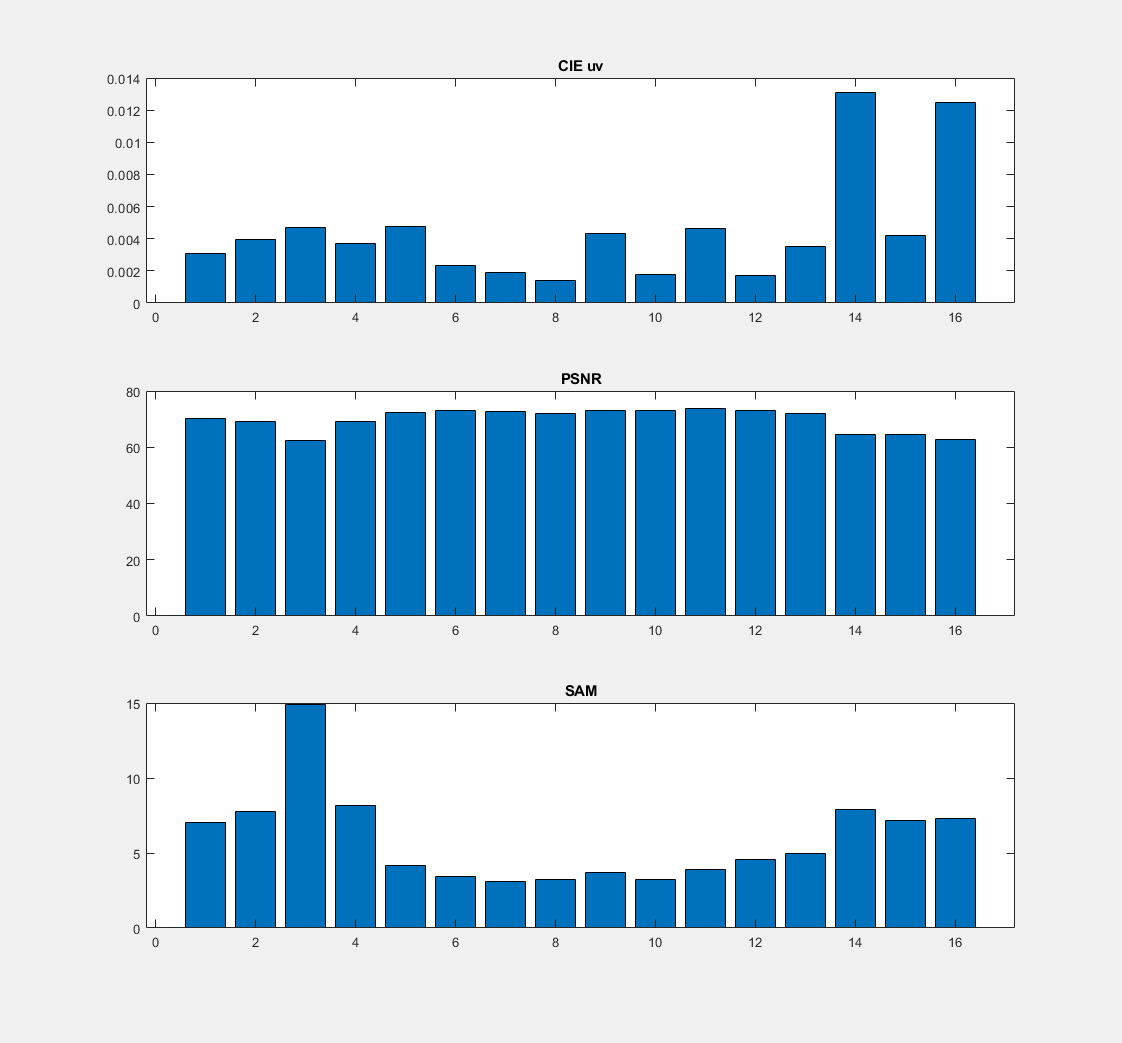

duv16 = zeros(16,1);
sam16 = zeros(16,1);
psnr16 = zeros(16,1);

for i=1:16
    spec_ref = ref16(i,1:10:401)';
    spec_mea = mea16(i,1:10:401)';
    duv16(i,1) = ColorConversionClass.spd2duv(spec_ref,spec_mea);
    sam16(i,1) = rad2deg(sam(spec_ref,spec_mea));
    psnr16(i,1) = psnr(spec_ref,spec_mea);
end

clf
subplot(3,1,1); bar(duv16); title('CIE uv')
subplot(3,1,2); bar(psnr16); title('PSNR')
subplot(3,1,3); bar(sam16); title('SAM')


eva_table = table(psnr16, sam16, duv16,'VariableNames',{'PSNR','SAM','du''v'''},'RowName',name16)

eva_table = 16×3 table
            PSNR      SAM        du'v'  
           ______    ______    _________

    D65     70.07    7.0536    0.0030703
    D50    69.214    7.7501    0.0039702
    A      62.381    14.897    0.0046933
    E      69.002    8.1679    0.0036828
    F1     72.313     4.168    0.0047718
    F2     73.047    3.4241    0.0023211
    F3     72.875    3.1248     0.001925
    F4     72.159    3.2593    0.0014152
    F5     73.041    3.6875    0.0043311
    F6       73.2    3.2504    0.0017763
    F7     73.683    3.9033     0.004635
    F8     72.997    4.5685    0.0017304
    F9     72.003    4.9611    0.0034969
    F10     64.65    

Matlab2latex.table2latex(eva_table)